# Derive Quadrotor Dynamics for Nonlinear Model Predictive Control

This example shows how to derive a continuous-time nonlinear model of a quadrotor using Symbolic Math Toolbox™. Specifically, this example discusses the `getQuadrotorDynamicsAndJacobian` script, which generates both the quadrotor state function and its Jacobian function. These functions are used in the [Control of Quadrotor Using Nonlinear Model Predictive Control](docid:mpc_ug#mw_8cbce3fe-f4d0-4f72-9682-21ca7ed6219b) example.

A quadrotor, also known as a quadcopter, is a helicopter with four rotors. From the center of mass of the quadrotor, rotors are placed in a square formation at equal distances. The quadrotor motion is controlled by adjusting the angular velocities of the four rotors, which are spun by electric motors. The mathematical model for the quadrotor dynamics can be derived from both the Newton–Euler and the Euler–Lagrange equations [1].

## Define State Variables and Parameters

The quadrotor has six degrees of freedom (three linear coordinates and three angular coordinates) with four control inputs as shown in this figure.

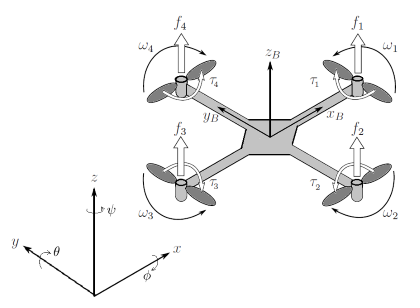

The 12 states of the quadrotor are


$${\left(x,y,z,\phi \;,\theta ,\psi ,\dot{x} ,\dot{y} ,\dot{z} ,\dot{\phi} ,\dot{\theta} ,\dot{\psi} \right)}^T ,$$


where:

- $\xi ={\left(x,y,z\right)}^{\mathrm{T}}$ represents the linear positions.

- $\eta ={\left(\phi \;,\theta ,\psi \right)}^{\mathrm{T}}$ represents the roll, pitch, and yaw angles, respectively.

- ${\left(\dot{x} ,\dot{y} ,\dot{z} ,\dot{\phi} ,\dot{\theta} ,\dot{\psi} \right)}^T$ represents the linear and angular velocities or the time-derivative of the linear and angular positions.

For the parameters of the quadrotor motion:

- $\left(u_1 ,u_2 ,u_3 ,u_4 \right)=\left(\omega_1^2 ,\omega_2^2 ,\omega_3^2 ,\omega_4^2 \right)$ represents the squared angular velocities of the four rotors.

- $\left(I_{\textrm{xx}} ,I_{\textrm{yy}} ,I_{\textrm{zz}} \right)$ represents the diagonal elements of the rotational inertia matrix in the body frame.

- $\left(k,l,m,b,g\right)$ represents the lift constant, rotor distance from center of mass, quadrotor mass, drag constant, and gravity.

The first four parameters $\left(u_1 ,u_2 ,u_3 ,u_4 \right)$ are control inputs or manipulated variables that control the quadrotor trajectory. The rest of the parameters are fixed with given values.

## Define Transformation Matrices and Coriolis Matrix

Define the matrices to transform between the inertial frame and the body frame. These transformation matrices are needed to describe the quadrotor motion in both frames. The 12 states of the quadrotor are defined in the inertial frame and the rotational inertia matrix is defined in the body frame.

Create symbolic functions to represent the time-dependent angles. This explicit time dependence is needed to evaluate the time derivatives in the mathematical derivation following [1]. Define the matrix ${\mathit{\mathbf{W}}}_{\eta \;}$ to transform the angular velocities from the inertial frame to the body frame. Define the rotation matrix $\mathit{\mathbf{R}}$ to transform the linear forces from the body frame to the inertial frame by using the `rotationMatrixEulerZYX` function defined in the Local Functions section. Create symbolic matrices to represent these transformation matrices.

% Create symbolic functions for time-dependent angles
% phi: roll angle
% theta: pitch angle
% psi: yaw angle
syms phi(t) theta(t) psi(t)

% Transformation matrix for angular velocities from inertial frame
% to body frame
W = [ 1,  0,        -sin(theta);
      0,  cos(phi),  cos(theta)*sin(phi);
      0, -sin(phi),  cos(theta)*cos(phi) ];

% Rotation matrix R_ZYX from body frame to inertial frame
R = rotationMatrixEulerZYX(phi,theta,psi);

Find the Jacobian matrix $\mathit{\mathbf{J}}={\mathit{\mathbf{W}}}_{\eta }^T \;\mathit{\mathbf{I}}{\mathit{\mathbf{W}}}_{\eta \;}$ that is used to express the rotational energy in the inertial frame.

% Create symbolic variables for diagonal elements of inertia matrix
syms Ixx Iyy Izz

% Jacobian that relates body frame to inertial frame velocities
I = [Ixx, 0, 0; 0, Iyy, 0; 0, 0, Izz];
J = W.'*I*W;

Next, find the Coriolis matrix $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)=\frac{\mathrm{d}}{\textrm{dt}}\mathit{\mathbf{J}}-\frac{1}{2}\frac{\partial }{\partial \eta \;}\left({\dot{\;\eta } }^{\mathrm{T}} \mathit{\mathbf{J}}\right)$ that contains the gyroscopic and centripetal terms in the angular Euler–Lagrange equations. Use the symbolic `diff` and `jacobian` functions to perform the differential operations. To simplify the notation for the Coriolis matrix after differentiations, substitute the explicit time-dependent terms in $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)$ with symbolic variables (that represent some values at a specific time). This simplified notation makes it easier to compare the result here with the derivation in [1].

% Coriolis matrix
dJ_dt = diff(J);
h_dot_J = [diff(phi,t), diff(theta,t), diff(psi,t)]*J;
grad_temp_h = transpose(jacobian(h_dot_J,[phi theta psi]));
C = dJ_dt - 1/2*grad_temp_h;
C = subsStateVars(C,t);

## Prove That Coriolis Matrix Definition Is Consistent

The Coriolis matrix $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)$ is easily derived using the symbolic workflow in the previous section. However, the definition of $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)$ here is different than in [1], which uses the Christoffel symbols to derive the Coriolis matrix. There can be multiple ways of defining $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)$ because it is nonunique. But, the term $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)\;\dot{\;\eta \;}$ that is used in the Euler–Lagrange equations must be unique. This section proves that the symbolic definition of $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)$ is consistent with the definition in [1] by showing that the term $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)\;\dot{\;\eta \;}$ is mathematically equal in both definitions. 

Evaluate the term $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)\;\dot{\;\eta \;}$ using the symbolic definition of $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)$ derived in the previous section.

% Evaluate C times etadot using symbolic definition
phidot   = subsStateVars(diff(phi,t),t);
thetadot = subsStateVars(diff(theta,t),t);
psidot   = subsStateVars(diff(psi,t),t);
Csym_etadot = C*[phidot; thetadot; psidot];

Evaluate the term $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)\;\dot{\;\eta \;}$ using the definition of $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)$ as derived in [1].

% Evaluate C times etadot using reference paper definition
C11 = 0;
C12 = (Iyy - Izz)*(thetadot*cos(phi)*sin(phi) + psidot*sin(phi)^2*cos(theta)) ...
      + (Izz - Iyy)*(psidot*cos(phi)^2*cos(theta)) - Ixx*psidot*cos(theta);
C13 = (Izz - Iyy)*psidot*cos(phi)*sin(phi)*cos(theta)^2;
C21 = (Izz - Iyy)*(thetadot*cos(phi)*sin(phi) + psidot*sin(phi)^2*cos(theta)) ...
      + (Iyy - Izz)*psidot*cos(phi)^2*cos(theta) + Ixx*psidot*cos(theta);
C22 = (Izz - Iyy)*phidot*cos(phi)*sin(phi);
C23 = - Ixx*psidot*sin(theta)*cos(theta) + Iyy*psidot*sin(phi)^2*sin(theta)*cos(theta) ...
      + Izz*psidot*cos(phi)^2*sin(theta)*cos(theta);
C31 = (Iyy - Izz)*psidot*cos(theta)^2*sin(phi)*cos(phi) - Ixx*thetadot*cos(theta);
C32 = (Izz - Iyy)*(thetadot*cos(phi)*sin(phi)*sin(theta) + phidot*sin(phi)^2*cos(theta)) ...
      + (Iyy - Izz)*phidot*cos(phi)^2*cos(theta) + Ixx*psidot*sin(theta)*cos(theta) ...
      - Iyy*psidot*sin(phi)^2*sin(theta)*cos(theta) - Izz*psidot*cos(phi)^2*sin(theta)*cos(theta);
C33 = (Iyy - Izz)*phidot*cos(phi)*sin(phi)*cos(theta)^2 ...
      - Iyy*thetadot*sin(phi)^2*cos(theta)*sin(theta) ...
      - Izz*thetadot*cos(phi)^2*cos(theta)*sin(theta) + Ixx*thetadot*cos(theta)*sin(theta);
Cpaper = [C11, C12, C13; C21, C22, C23; C31 C32 C33];
Cpaper_etadot = Cpaper*[phidot; thetadot; psidot];
Cpaper_etadot = subsStateVars(Cpaper_etadot,t);

Show that both definitions give the same result for the term $\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)\;\dot{\;\eta \;}$.

tf_Cdefinition = isAlways(Cpaper_etadot == Csym_etadot)

tf_Cdefinition = 3x1 logical array
   1
   1
   1


## Find Equations of Motion

Find the equations of motion for the 12 states.

Following [1], find the torques $\tau_B$ in the roll, pitch, and yaw angular directions:

- The roll movement is set by decreasing the 2nd rotor velocity and increasing the 4th rotor velocity.

- The pitch movement is set by decreasing the 1st rotor velocity and increasing the 3rd rotor velocity.

- The yaw movement is set by increasing the velocities of two opposite rotors and decreasing the velocities of the other two.

Find the total thrust of the rotors $T$ in the direction of the body $z$-axis.

% Define fixed parameters and control input
% k: lift constant
% l: distance between rotor and center of mass
% m: quadrotor mass
% b: drag constant
% g: gravity
% ui: squared angular velocity of rotor i as control input
syms k l m b g u1 u2 u3 u4

% Torques in the direction of phi, theta, psi
tau_beta = [l*k*(-u2+u4); l*k*(-u1+u3); b*(-u1+u2-u3+u4)];

% Total thrust
T = k*(u1+u2+u3+u4);

Next, create symbolic functions to represent the time-dependent positions. Define the 12 states $\left\lbrack \xi ;\eta ;\dot{\;\xi } ;\dot{\;\eta \;} \right\rbrack$ for the linear positions, angles, and their time derivatives. Once the states are defined, substitute the explicit time-dependent terms to simplify the notation.

% Create symbolic functions for time-dependent positions
syms x(t) y(t) z(t)

% Create state variables consisting of positions, angles,
% and their derivatives
state = [x; y; z; phi; theta; psi; diff(x,t); diff(y,t); ...
    diff(z,t); diff(phi,t); diff(theta,t); diff(psi,t)];
state = subsStateVars(state,t);

Create the 12 equations of motion that describe the time-derivative of the 12 states $f=\left\lbrack \dot{\;\xi } ;\dot{\;\eta \;} ;\ddot{\;\xi \;} ;\ddot{\;\eta \;} \right\rbrack$. The differential equations for the linear accelerations are $\;\ddot{\;\xi \;} =-{\left(0,0,g\right)}^{\mathrm{T}} +{\mathit{\mathbf{R}}\left(0,0,T\right)}^{\mathrm{T}} /m$. The differential equations for the angular accelerations are $\ddot{\;\eta \;} ={\mathit{\mathbf{J}}}^{-1} \left(\tau_B -\mathit{\mathbf{C}}\left(\eta ,\dot{\eta} \right)\dot{\;\eta \;} \right)$. Substitute the explicit time-dependent terms to simplify the notation. 

f = [ % Set time-derivative of the positions and angles
      state(7:12);

      % Equations for linear accelerations of the center of mass
      -g*[0;0;1] + R*[0;0;T]/m;

      % Euler–Lagrange equations for angular dynamics
      inv(J)*(tau_beta - C*state(10:12))
];

f = subsStateVars(f,t);

In previous steps, the fixed parameters are defined as symbolic variables to closely follow the derivation in [1]. Next, replace the fixed parameters with their given values. These values are used to design a trajectory tracking controller for a specific configuration of the quadrotor. After substituting the fixed parameters, perform algebraic simplification on the equations of motion by using `simplify`.

% Replace fixed parameters with given values here
IxxVal = 1.2;
IyyVal = 1.2;
IzzVal = 2.3;
kVal = 1;
lVal = 0.25;
mVal = 2;
bVal = 0.2;
gVal = 9.81;

f = subs(f, [Ixx Iyy Izz k l m b g], ...
    [IxxVal IyyVal IzzVal kVal lVal mVal bVal gVal]);
f = simplify(f);

## Find Jacobians and Generate Files for Nonlinear Model Predictive Control

Finally, find the analytical Jacobians of the nonlinear model functions and generate MATLAB® files using Symbolic Math Toolbox. This step is important to improve the computational efficiency when solving the nonlinear model for trajectory tracking using Model Predictive Control Toolbox™. For more information, see [nlmpc](docid:mpc_ref#mw_56547a96-970b-449a-929e-a3dadc671ab4) and [Specify Prediction Model for Nonlinear MPC](docid:mpc_ug#mw_cda3c7d0-97e5-4c33-9ec5-dcf440b4c5cf).

Find the Jacobians of the state function with respect to the state variables and control inputs.

% Calculate Jacobians for nonlinear prediction model
A = jacobian(f,state);
control = [u1; u2; u3; u4];
B = jacobian(f,control);

Generate MATLAB files for the state function and the Jacobians of the state function. These files can be used to design a trajectory tracking controller, as discussed in [Control of Quadrotor Using Nonlinear Model Predictive Control](docid:mpc_ug#mw_8cbce3fe-f4d0-4f72-9682-21ca7ed6219b).

% Create QuadrotorStateFcn.m with current state and control
% vectors as inputs and the state time-derivative as outputs
matlabFunction(f,'File','QuadrotorStateFcn', ...
    'Vars',{state,control});

% Create QuadrotorStateJacobianFcn.m with current state and control
% vectors as inputs and the Jacobians of the state time-derivative
% as outputs
matlabFunction(A,B,'File','QuadrotorStateJacobianFcn', ...
    'Vars',{state,control});

You can access the code in this script in the file `getQuadrotorDynamicsAndJacobian.m`.

## Local Functions

function [Rz,Ry,Rx] = rotationMatrixEulerZYX(phi,theta,psi)
% Euler ZYX angles convention
    Rx = [ 1,           0,          0;
           0,           cos(phi),  -sin(phi);
           0,           sin(phi),   cos(phi) ];
    Ry = [ cos(theta),  0,          sin(theta);
           0,           1,          0;
          -sin(theta),  0,          cos(theta) ];
    Rz = [cos(psi),    -sin(psi),   0;
          sin(psi),     cos(psi),   0;
          0,            0,          1 ];
    if nargout == 3
        % Return rotation matrix per axes
        return;
    end
    % Return rotation matrix from body frame to inertial frame
    Rz = Rz*Ry*Rx;
end

function stateExpr = subsStateVars(timeExpr,var)
    if nargin == 1 
        var = sym("t");
    end
    repDiff = @(ex) subsStateVarsDiff(ex,var);
    stateExpr = mapSymType(timeExpr,"diff",repDiff);
    repFun = @(ex) subsStateVarsFun(ex,var);
    stateExpr = mapSymType(stateExpr,"symfunOf",var,repFun);
    stateExpr = formula(stateExpr);
end

function newVar = subsStateVarsFun(funExpr,var)
    name = symFunType(funExpr);
    name = replace(name,"_Var","");
    stateVar = "_" + char(var);
    newVar = sym(name + stateVar);
end

function newVar = subsStateVarsDiff(diffExpr,var)
    if nargin == 1 
      var = sym("t");
    end
    c = children(diffExpr);
    if ~isSymType(c{1},"symfunOf",var)
      % not f(t)
      newVar = diffExpr;
      return;
    end
    if ~any([c{2:end}] == var)
      % not derivative wrt t only
      newVar = diffExpr;
      return;
    end
    name = symFunType(c{1});
    name = replace(name,"_Var","");
    extension = "_" + join(repelem("d",numel(c)-1),"") + "ot";
    stateVar = "_" + char(var);
    newVar = sym(name + extension + stateVar);
end

## References

[1] Raffo, Guilherme V., Manuel G. Ortega, and Francisco R. Rubio. "An integral predictive/nonlinear $\mathcal{H}_{\infty}$ control structure for a quadrotor helicopter". *Automatica 46*,  no. 1 (January 2010): 29–39. https://doi.org/10.1016/j.automatica.2009.10.018.

[2] Tzorakoleftherakis, Emmanouil, and Todd D. Murphey. "Iterative sequential action control for stable, model-based control of nonlinear systems." *IEEE Transactions on Automatic Control* 64, no. 8 (August 2019): 3170–83. https://doi.org/10.1109/TAC.2018.2885477.

[3] Luukkonen, Teppo. "Modelling and control of quadcopter". Independent research project in applied mathematics, Aalto University, 2011.

*Copyright 2019-2022 The MathWorks, Inc.*